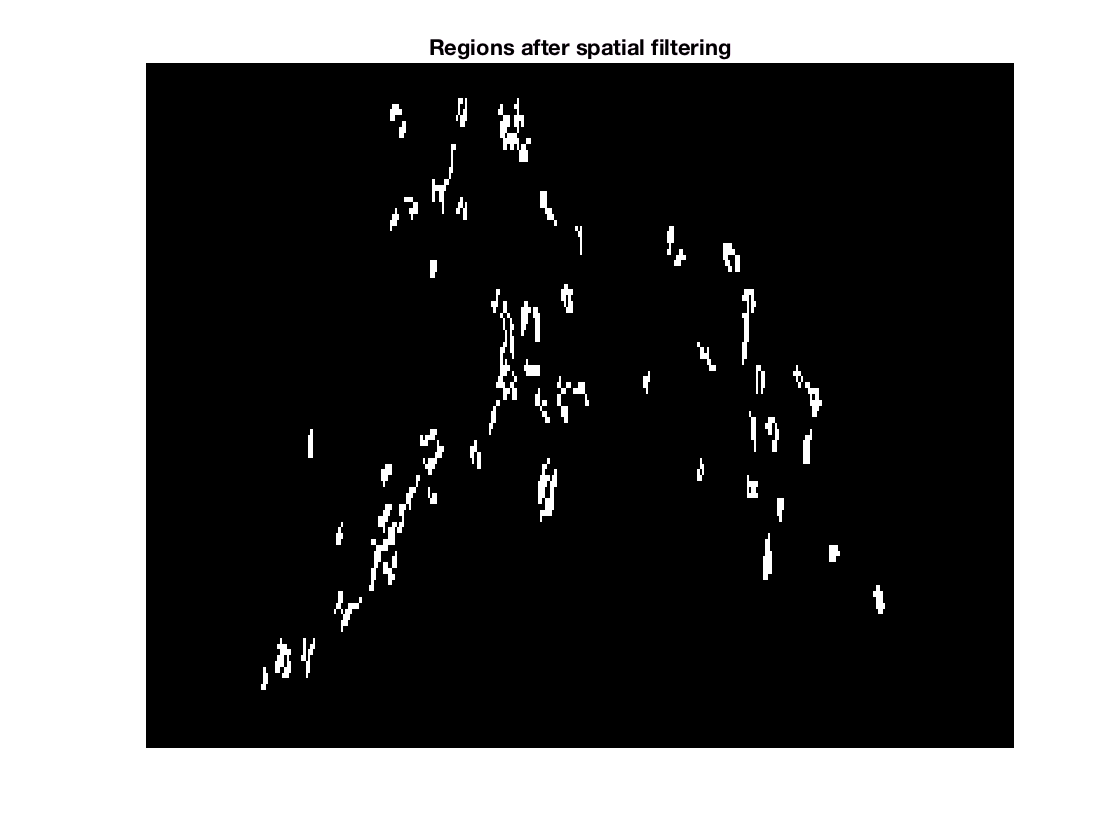

figure; 
imagesc(centroids_mask);
title('Regions after spatial filtering');
axis off;
colormap gray; 

colorbar off



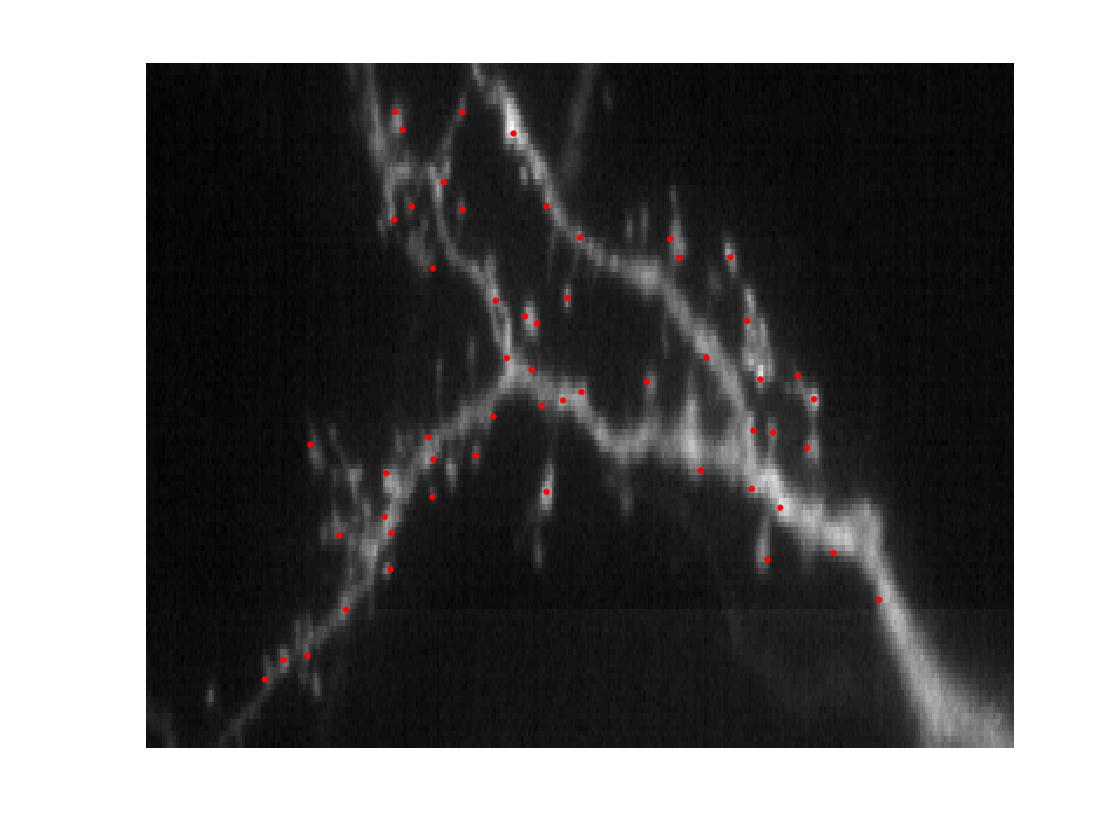

figure
imagesc(mean(data,3));
hold on;
for i = 1:size(component_centroids,1)
   plot(component_centroids(i,2),component_centroids(i,1),'r.','MarkerSize',10);
end
colormap gray
hold off;
axis off

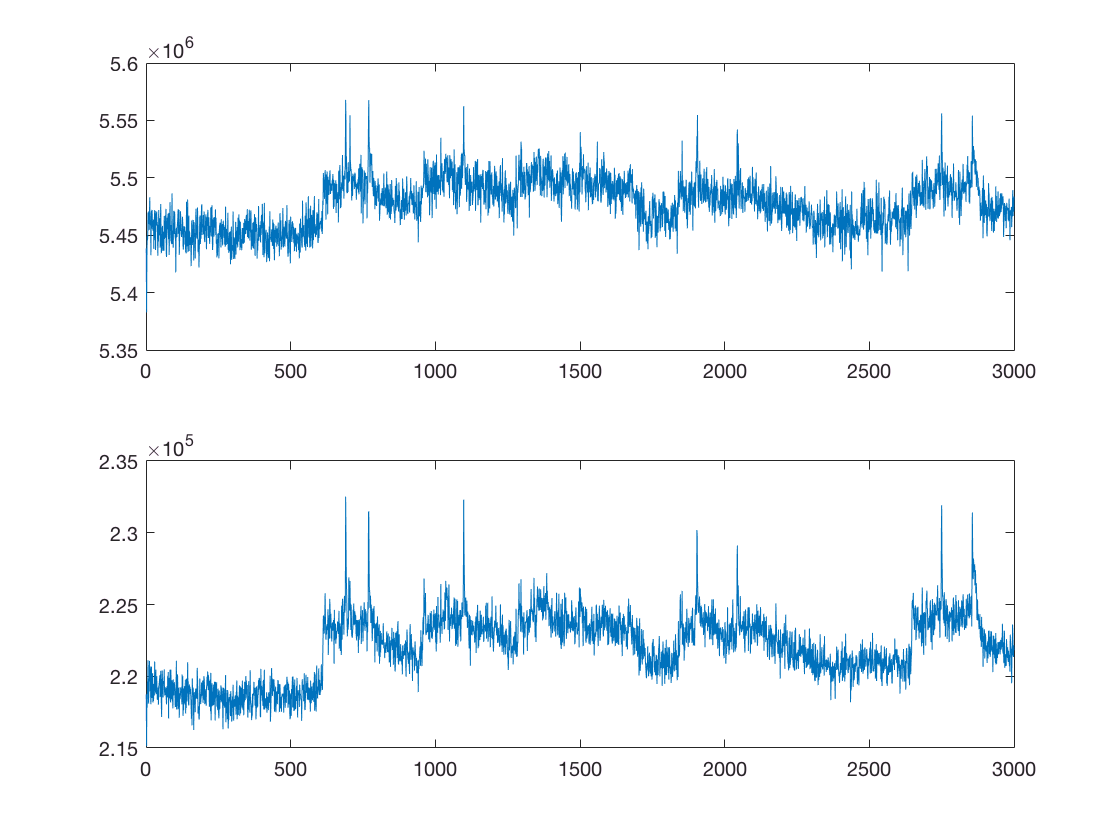



total_signal = squeeze(sum(sum(data,1),2));
figure;
filtered_data = bsxfun(@times,data,final_mask);
filtered_signal = squeeze(sum(sum(filtered_data,1),2));
subplot(2,1,1)
plot(total_signal)
subplot(2,1,2)
plot(filtered_signal)

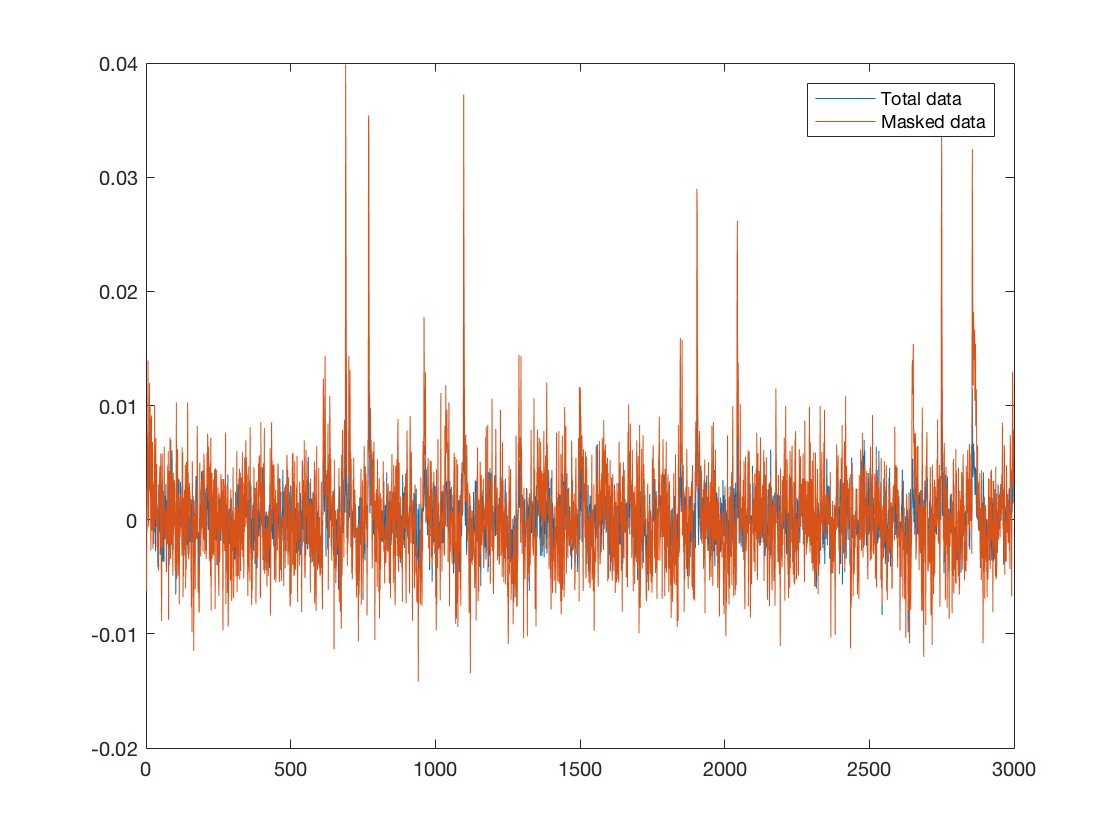

signal = total_signal;
mf = medfilt1(signal,100,[],1);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);

figure;
plot(instadff)
hold on;

signal = filtered_signal;
mf = medfilt1(signal,100,[],1);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
plot(instadff)
hold off; legend('Total data','Masked data');

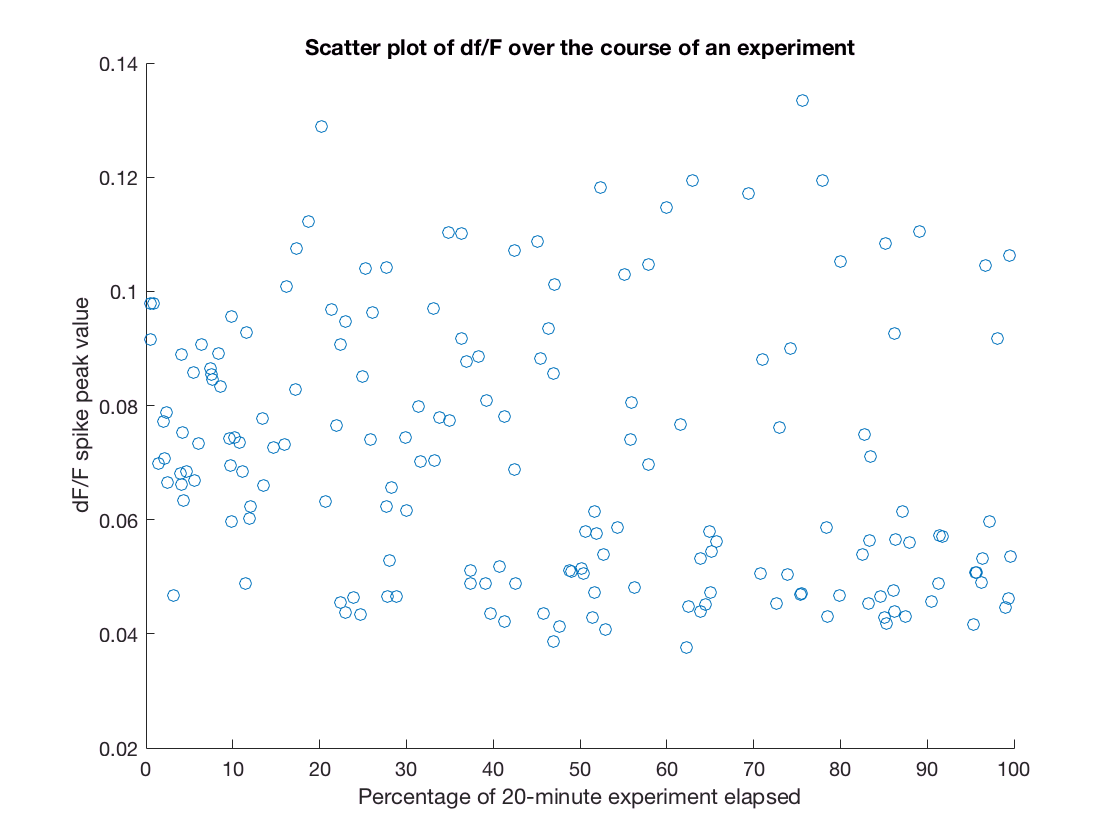

% Make a scatter plot of the peak sizes
signal = sum(component_thistories,1)./sum(component_sizes) - background_summed';

mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);



global_pks = getSpikes(instadff);

pk_values = instadff(global_pks);
pks_percentage = global_pks/length(instadff)*100;
figure;
scatter(pks_percentage,pk_values); 
title('Scatter plot of df/F over the course of an experiment')
ylabel('dF/F spike peak value')
xlabel('Percentage of 20-minute experiment elapsed')

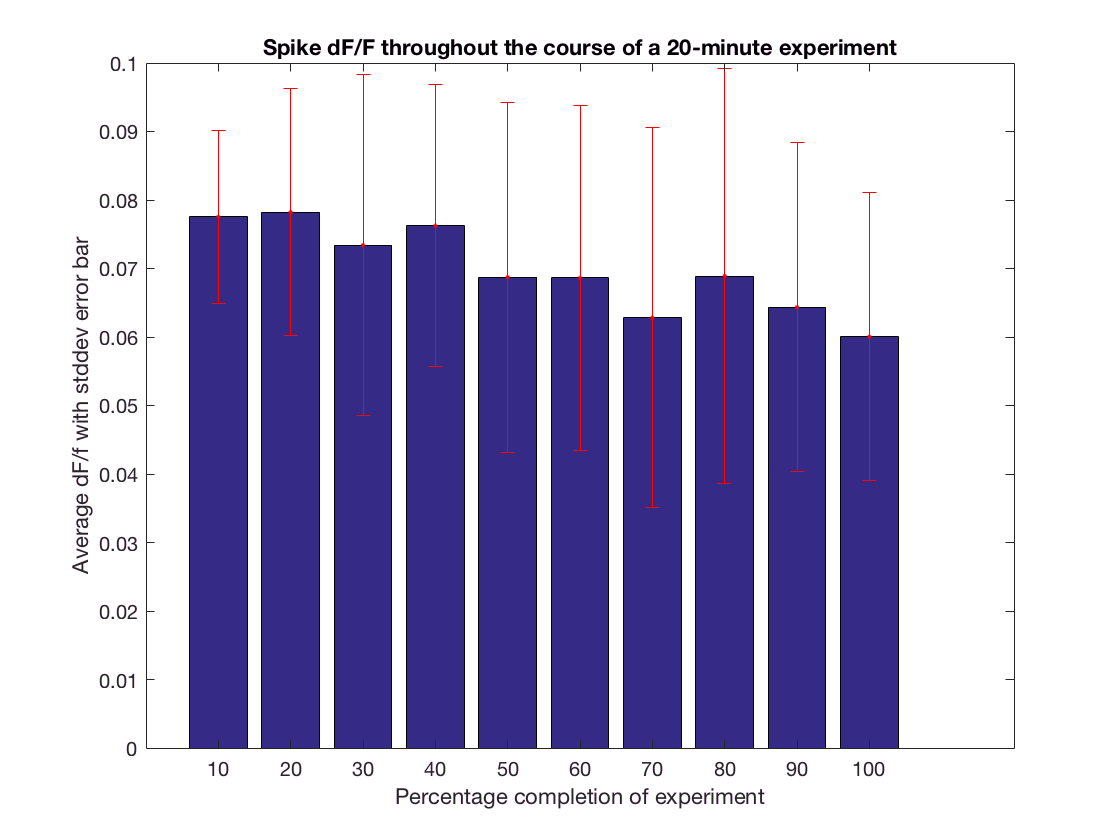


%Make a plot of spike statistics over time

% pk_values = instadff(global_pks);
% pks_percentage = global_pks/length(instadff)*100;
pk_means = [];
pk_stds = [];
for piece_idx = 1:10
    [~,I] = find(pks_percentage>(piece_idx-1)*10 & pks_percentage<(piece_idx)*10 );
    pk_values_for_subset = pk_values(I);
    pk_means(piece_idx) = mean(pk_values_for_subset);
    pk_stds(piece_idx) = std(pk_values_for_subset);
end

bar(10:10:100,pk_means); hold on;
errorbar(10:10:100,pk_means,pk_stds,'r.'); hold off;
title('Spike dF/F throughout the course of a 20-minute experiment')
ylabel('Average dF/f with stddev error bar')
xlabel('Percentage completion of experiment');

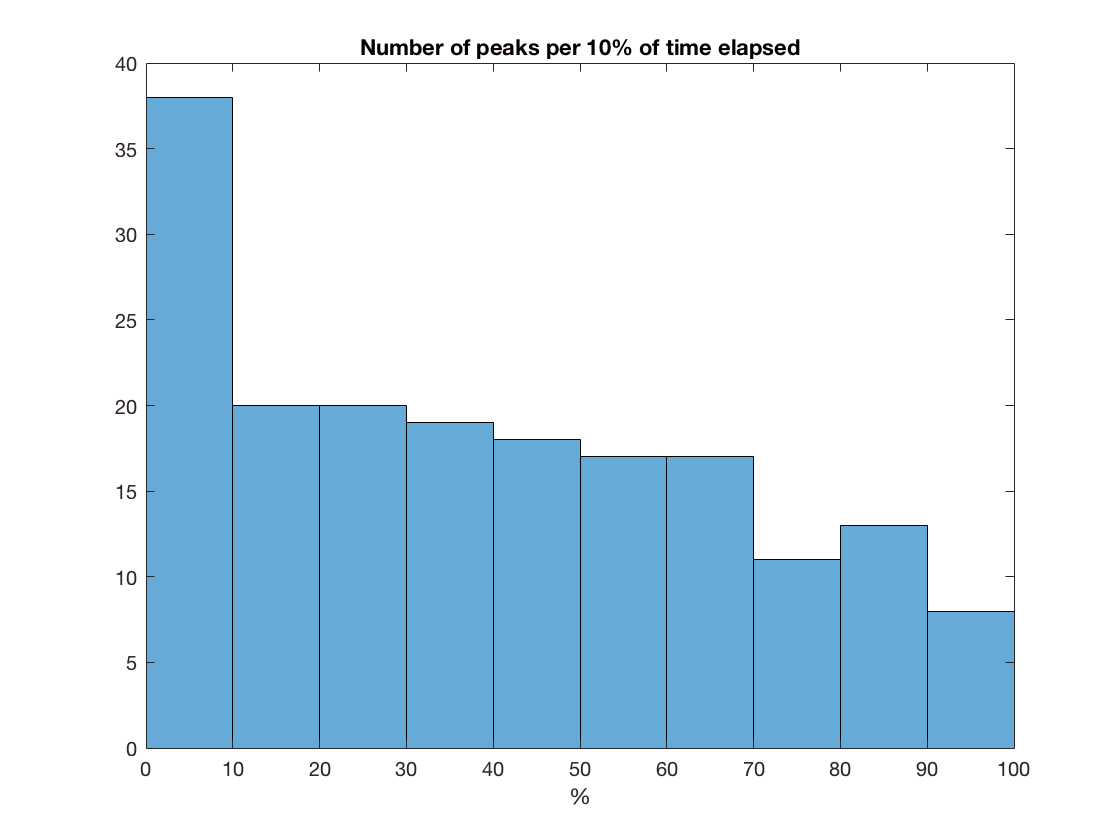

histogram(pks_percentage,10)
title('Number of peaks per 10% of time elapsed')
xlabel('%')

## Are these legit peaks? The .02 peaks make me wonder. Making a plot to zoom in

figure;
plot(instadff)

Undefined function or variable 'instadff'.

hold on;
plot(global_pks,pk_values,'g*'); 
hold off;
title('Exploring peaks')


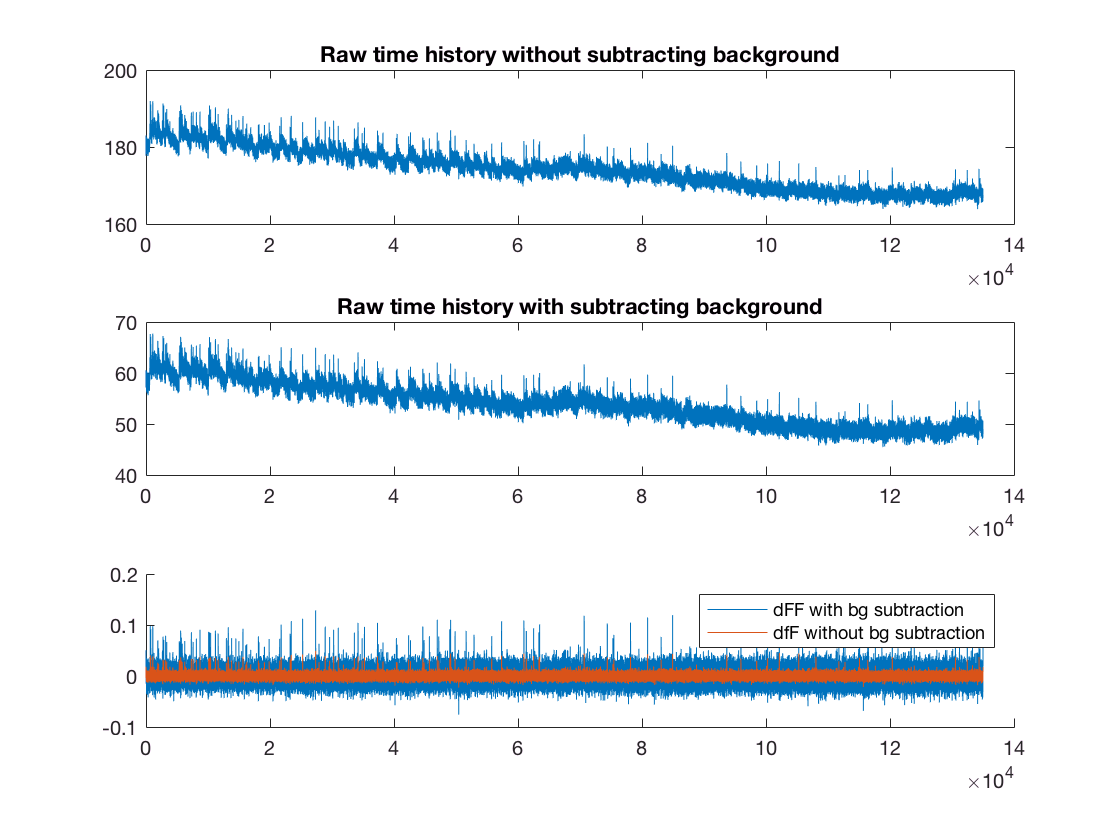

%Create a single dF/F the way Kiryl does:
f_bgsubtract = sum(component_thistories,1)./sum(component_sizes) - background_summed';
figure;
subplot(3,1,1)
plot(sum(component_thistories,1)./sum(component_sizes))
title('Raw time history without subtracting background')
subplot(3,1,2)
plot(f_bgsubtract)
title('Raw time history with subtracting background')
subplot(3,1,3)

signal = f_bgsubtract;

mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
hold on;
plot(instadff)
signal = sum(component_thistories,1)./sum(component_sizes);
mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
plot(instadff)
legend('dFF with bg subtraction', 'dfF without bg subtraction')
hold off

figure;
signal = f_bgsubtract;

Undefined function or variable 'f_bgsubtract'.

mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
hold on;
plot(instadff)

instadff_global = instadff; %Saving this value for later comparison

signal = sum(component_thistories,1)./sum(component_sizes);
mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
plot(instadff)
legend('dFF with bg subtraction', 'dfF without bg subtraction')
hold off

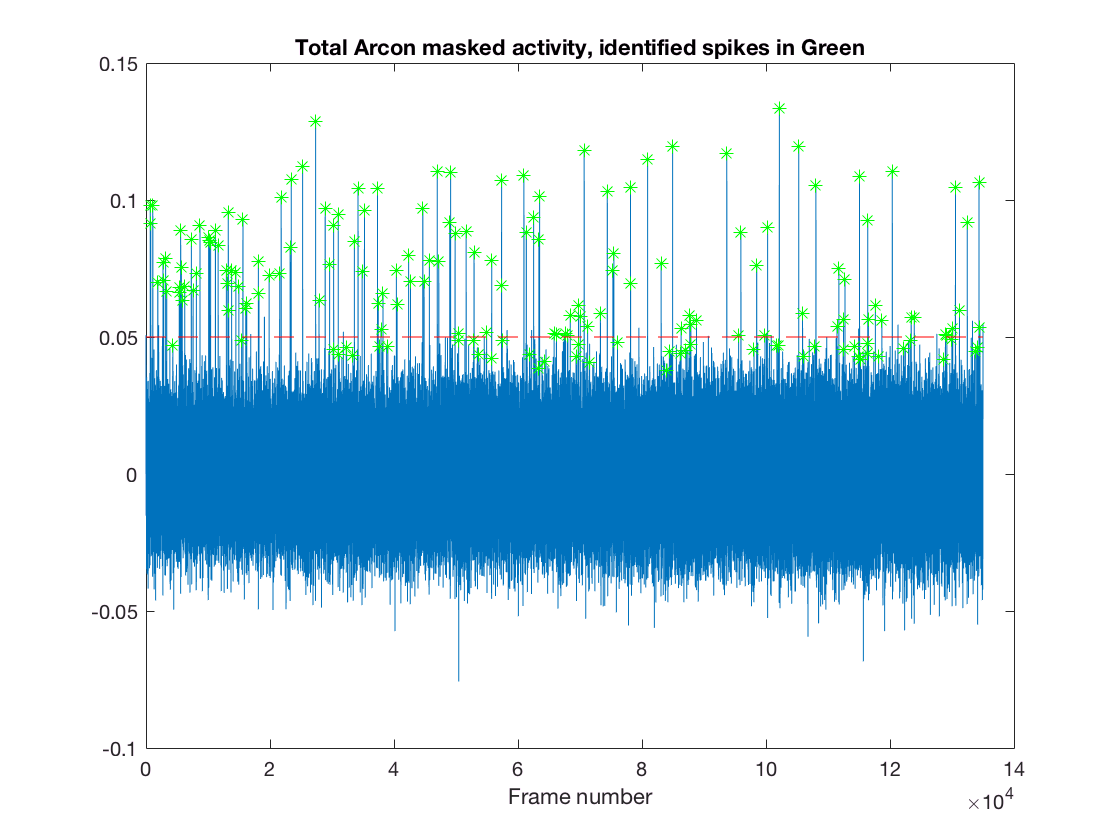

figure; 
plot(instadff_global); 
hold on; 
plot(global_pks,instadff(global_pks),'g*');
plot([1,length(instadff_global)],[.05, .05],'r--')
title('Total Arcon masked activity, identified spikes in Green');
xlabel('Frame number')
hold off;

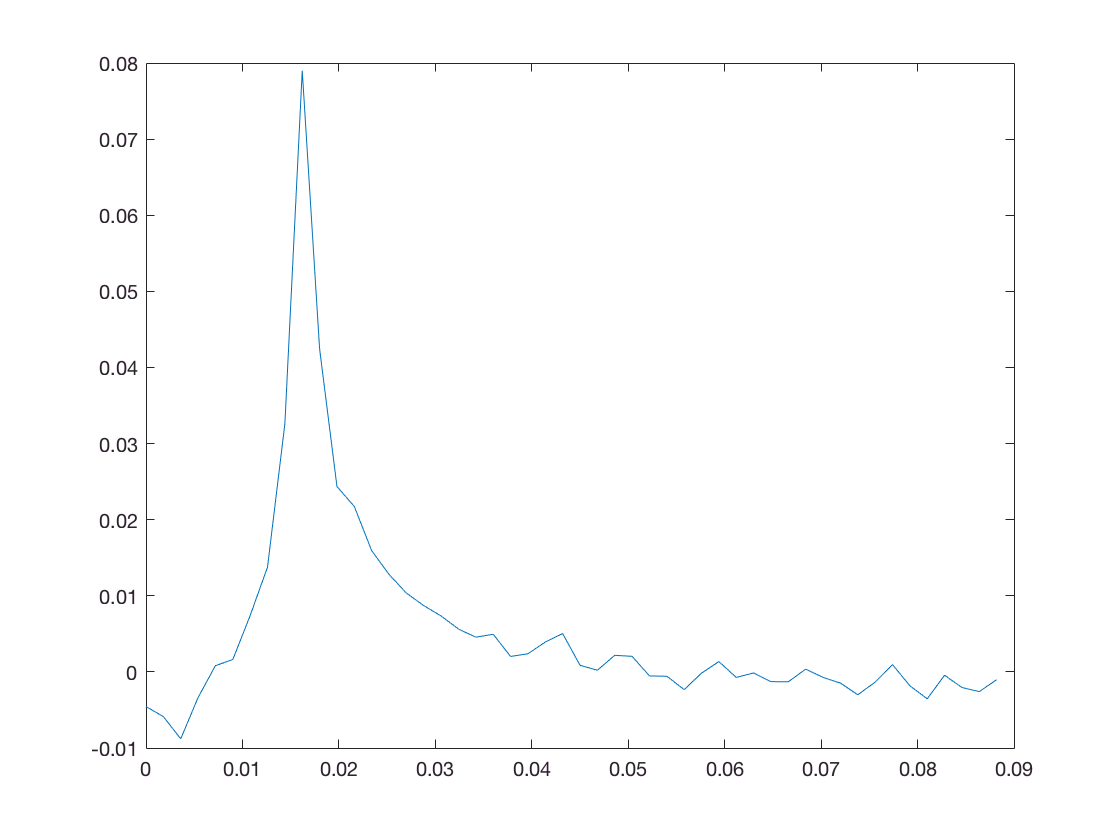

figure;
plot(t,mean(global_spike_history,1))

ylabel('dF/F')
xlabel('time (seconds)')
title('Averaged total spike activity over 131 events');
    

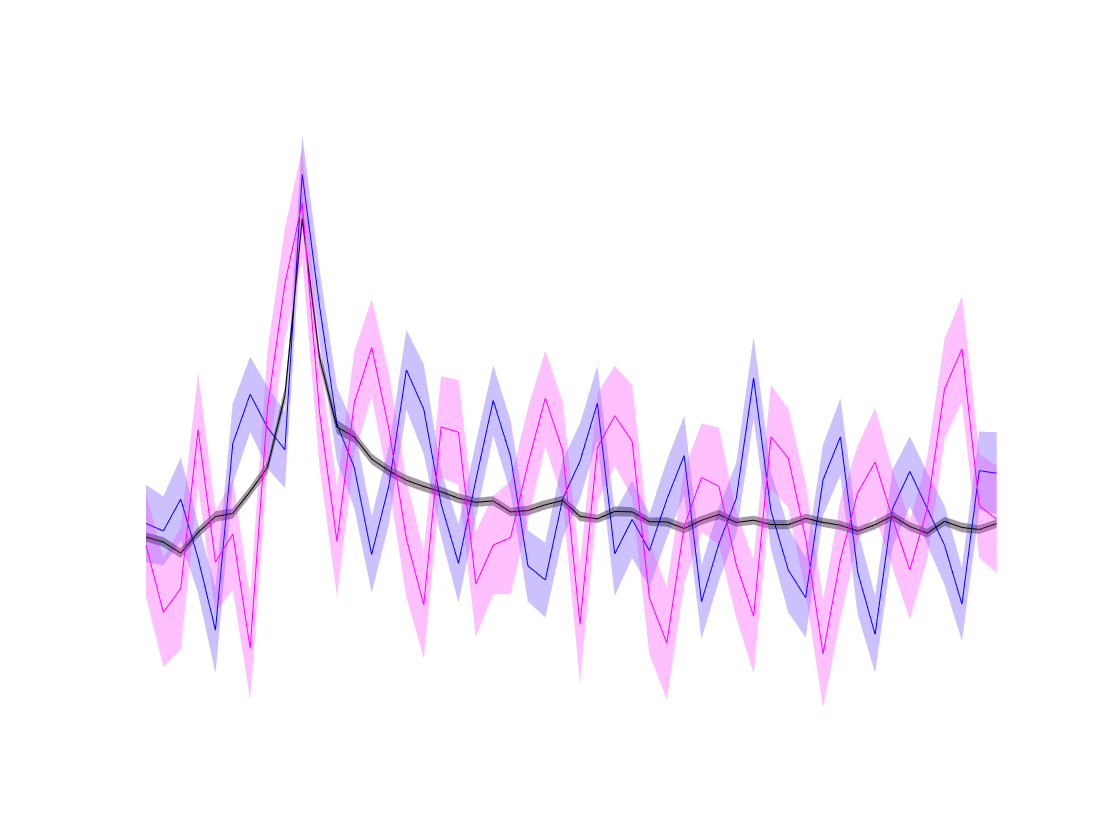

figure
filename = 'summed_spike_history.gif';
t = ([1:SAMPLES_BEFORE+SAMPLES_AFTER]-1)*1/Fs;
n = size(global_spike_history,1);
color_ctr = 1;
colors = {'b','m'};
for idx = [27,29]
%     plot(t,mean(global_spike_history,1))
%     errorbar(t,mean(global_spike_history,1),std(global_spike_history,1)/sqrt(n));
        [l,p] = boundedline(t, mean(global_spike_history,1), std(global_spike_history,1)/sqrt(n),'k', 'alpha');    
%         outlinebounds(l,p);
        hold on;
%     plot(t,median(global_spike_history,1),'b--');
    
%     plot(t,mean(squeeze(roi_spike_history(idx,:,:)),1),'r');
%     errorbar(t,mean(squeeze(roi_spike_history(idx,:,:)),1),std(squeeze(roi_spike_history(idx,:,:)),1)/sqrt(n),'r')    
    [l,p] = boundedline(t, mean(squeeze(roi_spike_history(idx,:,:)),1), std(squeeze(roi_spike_history(idx,:,:)),1)/sqrt(n),colors{color_ctr}, 'alpha');    
%        outlinebounds(l,p);
%     plot(t,median(squeeze(roi_spike_history(idx,:,:)),1),'r--');
    
    
%    plot(t,0*mean(global_spike_history,1),'k--');  

    %     plot(t,mean(squeeze(roi_spike_history(idx,:,:)),1))
    hold off;
%     title(sprintf('ROI idx = %i',idx));
    xlabel('Time, seconds')
    ylabel('Summed time history');
%     legend('Mean dendrite spike activity','Mean ROI activity');
    NumTicks = 10; L =get(gca,'XLim');
    set(gca,'XTick',linspace(L(1),L(2),NumTicks))
    
    axis off;
    color_ctr = color_ctr+1;
end

figure; 
imagesc(centroids_mask);
title('Regions after spatial filtering');
axis off;
colormap gray; 
colorbar off



figure
imagesc(mean(data,3));
hold on;
for i = 1:size(component_centroids,1)
   plot(component_centroids(i,2),component_centroids(i,1),'r.','MarkerSize',10);
end
colormap gray
hold off;
axis off


total_signal = squeeze(sum(sum(data,1),2));
figure;
filtered_data = bsxfun(@times,data,final_mask);
filtered_signal = squeeze(sum(sum(filtered_data,1),2));
subplot(2,1,1)
plot(total_signal)
subplot(2,1,2)
plot(filtered_signal)

signal = total_signal;
mf = medfilt1(signal,100,[],1);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);

figure;
plot(instadff)
hold on;

signal = filtered_signal;
mf = medfilt1(signal,100,[],1);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
plot(instadff)
hold off; legend('Total data','Masked data');





% Make a scatter plot of the peak sizes
signal = sum(component_thistories,1)./sum(component_sizes) - background_summed';

mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);



global_pks = getSpikes(instadff);

pk_values = instadff(global_pks);
pks_percentage = global_pks/length(instadff)*100;
figure;
scatter(pks_percentage,pk_values); 
title('Scatter plot of df/F over the course of an experiment')
ylabel('dF/F spike peak value')
xlabel('Percentage of 20-minute experiment elapsed')

%Make a plot of spike statistics over time

% pk_values = instadff(global_pks);
% pks_percentage = global_pks/length(instadff)*100;
pk_means = [];
pk_stds = [];
for piece_idx = 1:10
    [~,I] = find(pks_percentage>(piece_idx-1)*10 & pks_percentage<(piece_idx)*10 );
    pk_values_for_subset = pk_values(I);
    pk_means(piece_idx) = mean(pk_values_for_subset);
    pk_stds(piece_idx) = std(pk_values_for_subset);
end

bar(10:10:100,pk_means); hold on;
errorbar(10:10:100,pk_means,pk_stds,'r.'); hold off;
title('Spike dF/F throughout the course of a 20-minute experiment')
ylabel('Average dF/f with stddev error bar')
xlabel('Percentage completion of experiment');

histogram(pks_percentage,10)
title('Number of peaks per 10% of time elapsed')
xlabel('%')

## Are these legit peaks? The .02 peaks make me wonder. Making a plot to zoom in

figure;
plot(instadff)
hold on;
plot(global_pks,pk_values,'g*'); 
hold off;
title('Exploring peaks')


%Create a single dF/F the way Kiryl does:
f_bgsubtract = sum(component_thistories,1)./sum(component_sizes) - background_summed';
figure;
subplot(3,1,1)
plot(sum(component_thistories,1)./sum(component_sizes))
title('Raw time history without subtracting background')
subplot(3,1,2)
plot(f_bgsubtract)
title('Raw time history with subtracting background')
subplot(3,1,3)

signal = f_bgsubtract;

mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
hold on;
plot(instadff)
signal = sum(component_thistories,1)./sum(component_sizes);
mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
plot(instadff)
legend('dFF with bg subtraction', 'dfF without bg subtraction')
hold off

figure;
signal = f_bgsubtract;
mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
hold on;
plot(instadff)

instadff_global = instadff; %Saving this value for later comparison

signal = sum(component_thistories,1)./sum(component_sizes);
mf = medfilt1(signal,100,[],2);
instadff = signal./mf-1;
instadff(1) = instadff(2);
instadff(end) = instadff(end-1);
plot(instadff)
legend('dFF with bg subtraction', 'dfF without bg subtraction')
hold off

figure; 
plot(instadff_global); 
hold on; 
plot(global_pks,instadff(global_pks),'g*');
plot([1,length(instadff_global)],[.05, .05],'r--')
title('Total Arcon masked activity, identified spikes in Green');
xlabel('Frame number')
hold off;
figure;
plot(t,mean(global_spike_history,1))
ylabel('dF/F')
xlabel('time (seconds)')
title('Averaged total spike activity over 131 events');
    

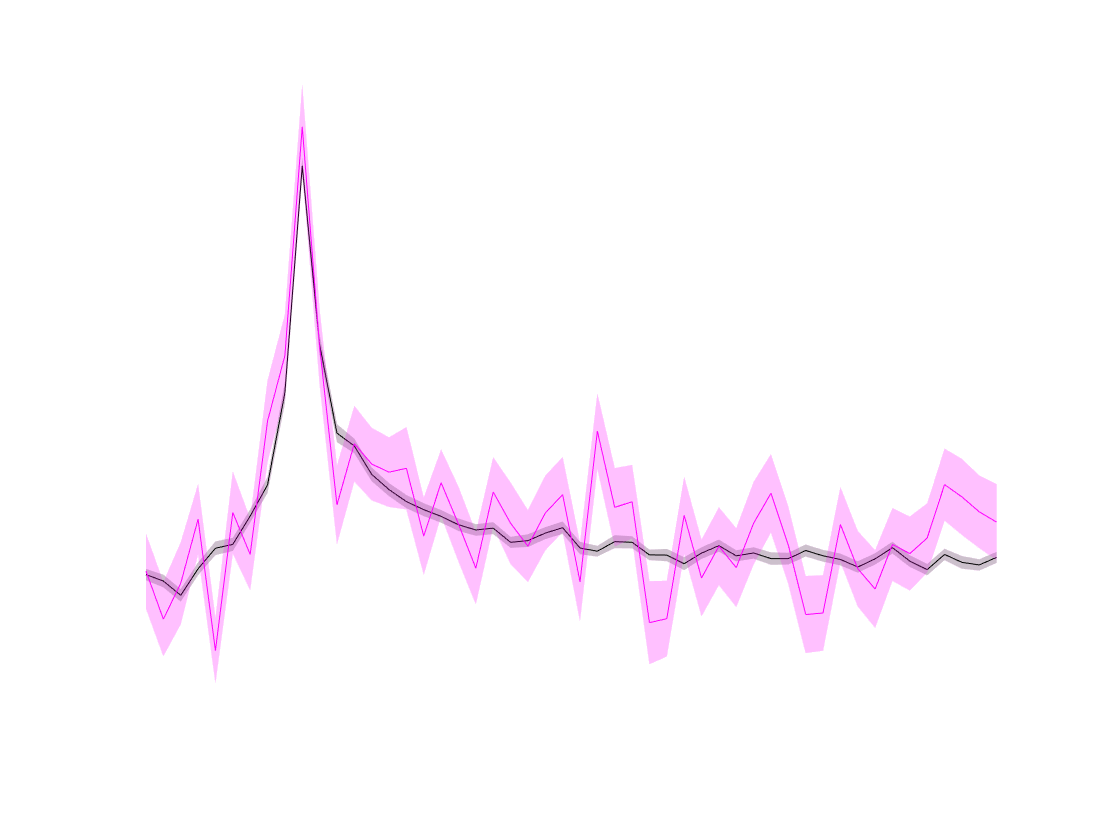

figure
filename = 'summed_spike_history.gif';
t = ([1:SAMPLES_BEFORE+SAMPLES_AFTER]-1)*1/Fs;
n = size(global_spike_history,1);
color_ctr = 1;
colors = {'m'};


[l,p] = boundedline(t, mean(global_spike_history,1), std(global_spike_history,1)/sqrt(n),'k', 'alpha');    

hold on;

combined_spike_history = squeeze(mean(roi_spike_history([27,29],:,:),1));
[l,p] = boundedline(t, mean(combined_spike_history,1), std(combined_spike_history,1)/sqrt(n),colors{color_ctr}, 'alpha');    
hold off;

xlabel('Time, seconds')
ylabel('Summed time history');

NumTicks = 10; L =get(gca,'XLim');
set(gca,'XTick',linspace(L(1),L(2),NumTicks))

axis on;

color_ctr = color_ctr+1;

